# Sparity of Dynamical Regression Vector

addpath("utils\")

## Test matlab function generated with Python

DynRegExample=DynRegVec([0,0,0,0,0,0]);
DynRegVecLength=length(DynRegExample);

## Generate Random Kinematics

Random seed

rng(42);

Dataset size

dataset_size=5e4;

Kinematics dataset

KinematicsData=rand(dataset_size,2*3);
KinematicsData(:,1:2)=2*pi*KinematicsData(:,1:2);
KinematicsData(:,3:4)=2*1.5*(KinematicsData(:,3:4)-0.5);
KinematicsData(:,5:6)=2*5*(KinematicsData(:,5:6)-0.5);

## Generate Dynamical Regression Vector Dataset

DynRegData=zeros(dataset_size,DynRegVecLength);
for i=1:dataset_size
    DynRegData(i,:)=transpose(DynRegVec(KinematicsData(i,:)));
end

## Sparity Analysis

Normalize Data

DynRegData_Normalized=zeros(dataset_size,DynRegVecLength);
for i=1:DynRegVecLength
    if DynRegData(:,i)==zeros(dataset_size,1)
        DynRegData_Normalized(:,i)=zeros(dataset_size,1);
    else
        DynRegData_Normalized(:,i)=normalize(DynRegData(:,i));
    end
end

Obtain Singular Value

s=svd(DynRegData_Normalized);

Visualization

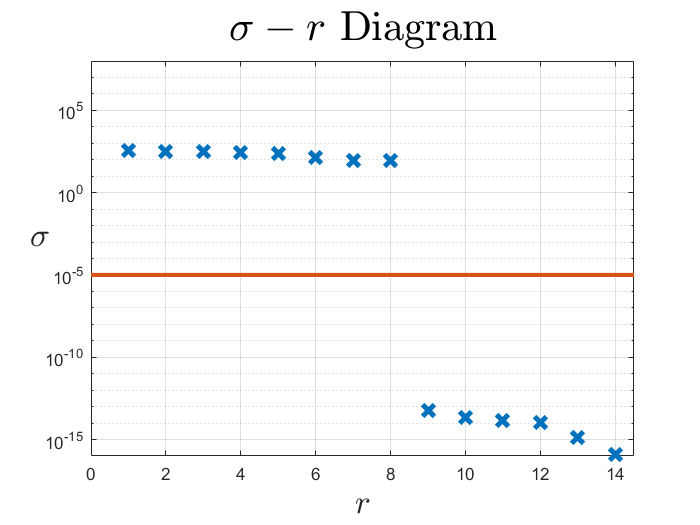

semilogy(s(1:DynRegVecLength),"x","MarkerFaceColor","blue","MarkerSize",10,"LineWidth",3);
hold on
plot([0,length(s)+1],1e-5*[1,1],"LineWidth",2.5);
hold off
grid on
xlabel("$r$","FontSize",20,"Interpreter","latex")
ylabel("$\sigma$","Rotation",0,"FontSize",20,"Interpreter","latex")
title("$\sigma-r$ Diagram","FontSize",25,"Interpreter","latex")
ylim([10^-16,10^8])
xlim([0,DynRegVecLength+0.5])

## Save Data

% KinematicsTable=array2table(KinematicsData,"VariableNames", ...
%     ["theta_1","theta_2","dtheta_1","dtheta_2","ddtheta_1","ddtheta_2"]);
% writetable(KinematicsTable,"Data\KinematicsData.csv")
% writematrix(DynRegData,"Data\DynRegVecData.csv")
save("Data\KinematicsData.mat","KinematicsData")
save("Data\DynRegVecData.mat","DynRegData")

Remove path

rmpath("utils\")

## Result from `rank()` Function

disp("Rank with rank() function is "+num2str(rank(DynRegData))+".")

Rank with rank() function is 8.
